# Diagram of signal processing  

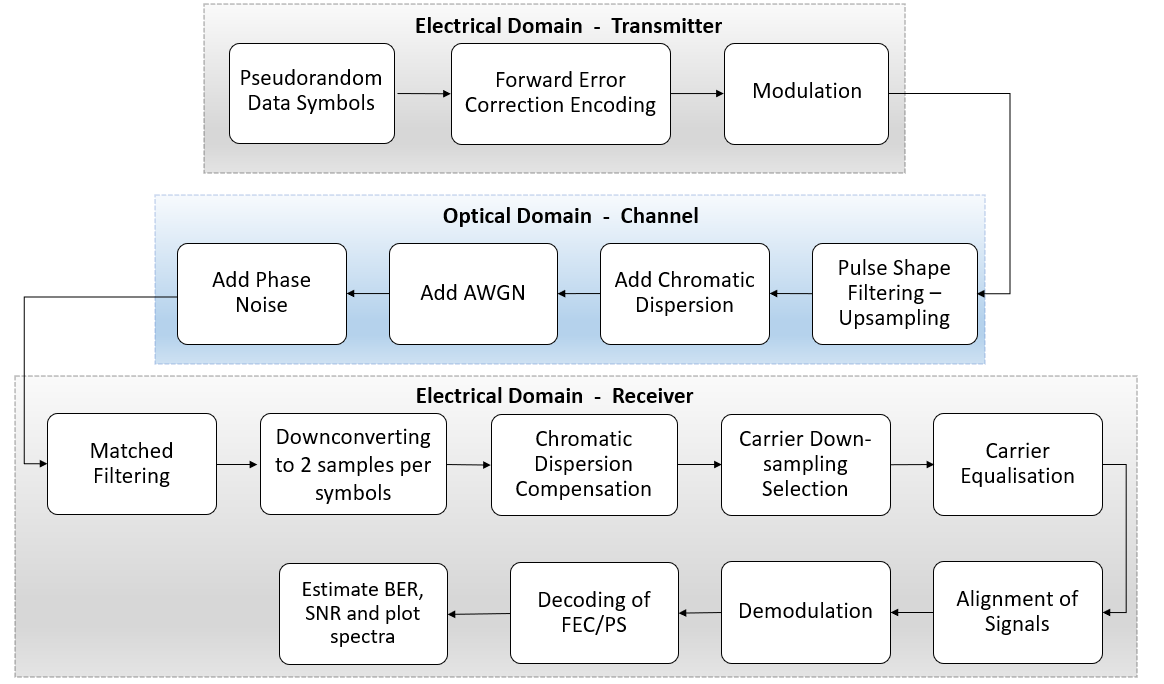

## Constants and Initial Conditions

clearvars;
tic
%Resetting the rng seed
%rng("default");
%rng(1960);

purple = [0.75,0,0.75];

enable_FEC = false;

enable_pulse_shaping = true;
enable_downsampling = true;

enable_alignment = true;

enable_AWGN = true;
enable_phase_noise = true;
enable_chromatic_dispersion = true; %This should only be done in tandem to pulse shaping
enable_adaptive_eq = true;

enable_frequency_equal = false; %No implementation
enable_carrier_equal = false;
enable_plots = true;

% Need coupling component implemented
% Need Non-linearities tested and introduced


num_symbols = 32*1024;
symbol_rate = 50e9;
time_step = 1/symbol_rate;
linewidth = 100e3; %Hz
variance = 2*pi*linewidth*time_step;


%Modulation Orders
M1 = 2;
M2 = 4;
M3 = 16;
M4 = 64;

%Bits/Symbol
k1 = log2(M1);
k2 = log2(M2);
k3 = log2(M3);
k4 = log2(M4);

%Transmitted Bits
b_bits = k1*num_symbols;
q_bits = k2*num_symbols;
qam16_bits = k3*num_symbols;
qam64_bits = k4*num_symbols;

## Forward Error Correction

if enable_FEC
    
    LDPC = dvbs2ldpc(3/4);
    encLDPC = comm.LDPCEncoder(LDPC); %#ok<*UNRCH>
    
    % K: uncoded message length
    % N: coded message length
    LDPC_K = size(LDPC,2)-size(LDPC,1);
    LDPC_N = size(LDPC,2);
    
    symbols_bi = randi([0 M1-1],num_symbols,1);
    
    %% nK-by-1 column vector of binary data where K = (3/4)*64800 = 48600n
    padding = (floor(length(symbols_bi)/LDPC_K)+1)*LDPC_K-length(symbols_bi);
    
    padding = padding/2; %Halve for adding to both sides
    
    symbols_b = reshape(padarray(symbols_bi,padding,"both"),LDPC_K,[]);
    
    if(length(symbols_b)~=LDPC_K)
        error("Incorrect dimension for encoding");
    end
    
    %BPSK Encoding
    
    symbols_temp = nan(LDPC_N,size(symbols_b,2));
    
    for i=1:size(symbols_b,2)
        symbols_temp(:,i) = encLDPC(symbols_b(:,i));
    end
    symbols_b = reshape(symbols_temp,1,[]);
    
    %QPSK Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols.
    
    symbols_qi = randi([0 M2-1],num_symbols,1);
    symbols_q = conversion(encLDPC,symbols_qi,M2,LDPC_K,LDPC_N);
    
    %QAM16 Encoding
    %LDPCs only take binary inputs, will have to convert symbols to bits, encode,
    %convert to symbols again,  and for decoding, symbols to bits, decode,
    %bits to symbols.
    
    symbols_16i = randi([0 M3-1],num_symbols,1);
    symbols_16 = conversion(encLDPC,symbols_16i,M3,LDPC_K,LDPC_N);
    
    
    symbols_64i = randi([0 M4-1],num_symbols,1);
    symbols_64 = conversion(encLDPC,symbols_64i,M4,LDPC_K,LDPC_N);
    
end

## Modulation

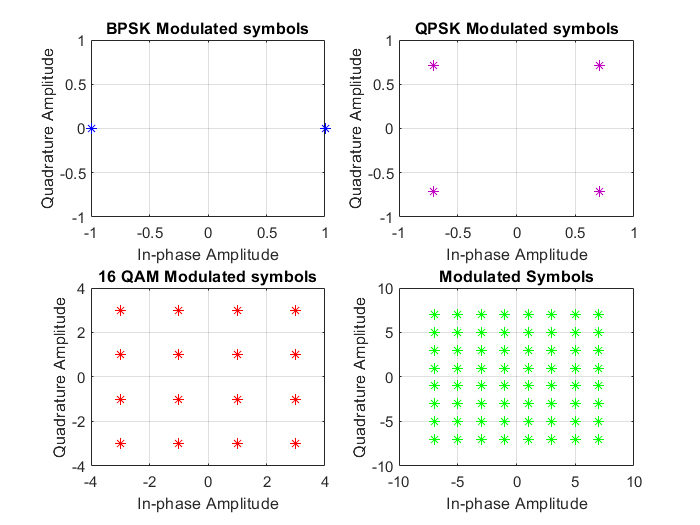

%BPSK
if (~enable_FEC)
    symbols_b = randi([0 M1-1],1,num_symbols);
end
bpsk_mod = pskmod(symbols_b,M1,0,'gray');


%QPSK
if (~enable_FEC)
    symbols_q = randi([0 M2-1],1,num_symbols);
end
qpsk_mod = pskmod(symbols_q,M2,pi/M2,'gray');


%16QAM
if (~enable_FEC)
    symbols_16 = randi([0 M3-1],1,num_symbols);
end
qam16_mod = qammod(symbols_16,M3,'gray');


%64QAM
if (~enable_FEC)
    symbols_64 = randi([0 M4-1],1,num_symbols);
end
qam64_mod = qammod(symbols_64,M4,'gray');

if enable_plots
    figure
    subplot(2,2,1,gca);
    plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
    title("BPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    xlim([-1,1]);
    ylim([-1,1]);
    grid on;
    subplot(2,2,2);
    grid on;
    plot(qpsk_mod,'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,3);
    plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
    title("16 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,4);
    plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
    title("64 QAM Modulated symbols");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    title("Modulated Symbols");
    grid on;
end

# **Transition into the Optical Domain (TX)**

## Pulse Shaping and Upconverting

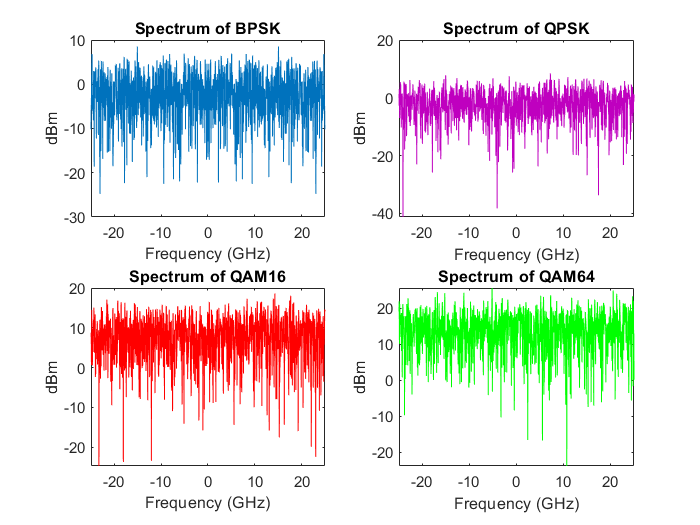

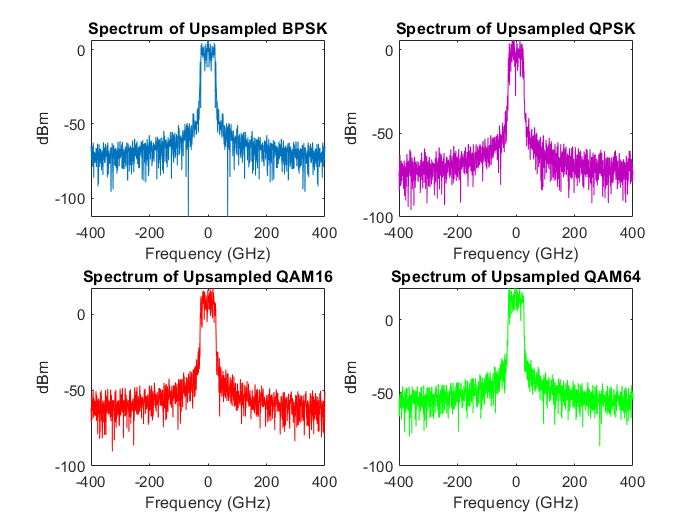

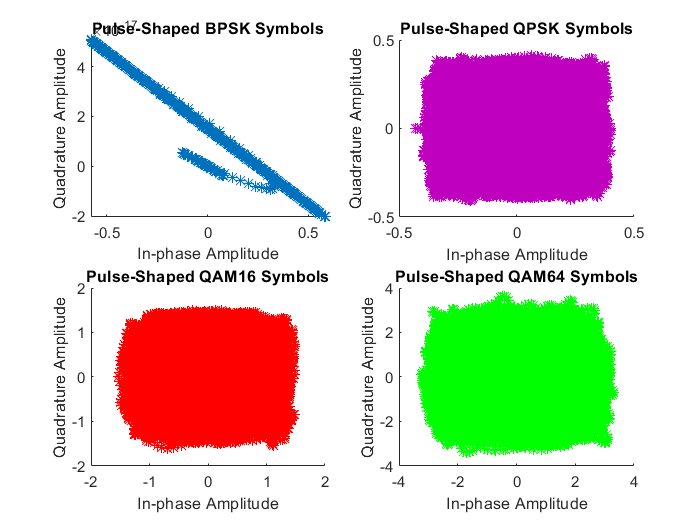

    span = 20;
    upsampling = 16;
    Rolloff = 0.1;
    receiver_samples_per_symbol = 2; 
    correl = true;
    
if enable_pulse_shaping
    
    
    
    %Define Filter Constants
    
    %These might not be defined correctly
    optical_sample_rate = symbol_rate*upsampling;
    num_optical_samples = num_symbols*upsampling;
    receiver_sample_rate = receiver_samples_per_symbol*symbol_rate;
    num_samples = num_symbols*receiver_samples_per_symbol;
    %Define Filter Objects
    
    tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",span,"OutputSamplesPerSymbol",upsampling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",span,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling/receiver_samples_per_symbol,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    
 %% Filter Delays as defined in example sent (usage unclear)
    % filtDelay_b = k1*span;
    % filtDelay_q = k2*span;
    % filtDelay_qam16 = k3*span;
    % filtDelay_qam64 = k4*span;
    
    %Inspect Filters
    
    if enable_plots
        %fvtool(tx_ps_filter);
        filter_taps = coeffs(tx_ps_filter);
        filter_taps = filter_taps.Numerator;
        
        raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',optical_sample_rate);
        hide(raised_cosine_scope);
        matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate);
        hide(matched_scope);
        
        
        figure
        
        subplot(2,2,1,gca);
        matched_scope(bpsk_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:});
        title("Spectrum of BPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,2);
        matched_scope(qpsk_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color',purple);
        title("Spectrum of QPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,3);
        matched_scope(qam16_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','red');
        title("Spectrum of QAM16");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,4);
        matched_scope(qam64_mod.');
        data = getSpectrumData(matched_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','green');
        title("Spectrum of QAM64");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
    end
    
     
    if correl
        corr_bpsk = bpsk_mod;
        corr_qpsk = qpsk_mod;
        corr_qam16 = qam16_mod;
        corr_qam64 = qam64_mod;
    end
    
    
    %Filter Transmitted Signals
    bpsk_mod = tx_ps_filter(bpsk_mod.').';
    qpsk_mod = tx_ps_filter(qpsk_mod.').';
    qam16_mod = tx_ps_filter(qam16_mod.').';
    qam64_mod = tx_ps_filter(qam64_mod.').';
    
    if enable_plots
        
        figure
        subplot(2,2,1,gca);
        raised_cosine_scope(bpsk_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:});
        title("Spectrum of Upsampled BPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,2);
        raised_cosine_scope(qpsk_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color',purple);
        title("Spectrum of Upsampled QPSK");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,3);
        raised_cosine_scope(qam16_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','red');
        title("Spectrum of Upsampled QAM16");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        subplot(2,2,4);
        raised_cosine_scope(qam64_mod.');
        data = getSpectrumData(raised_cosine_scope);
        plot(data.FrequencyVector{:}/1e9,data.Spectrum{:},'Color','green');
        title("Spectrum of Upsampled QAM64");
        xlabel("Frequency (GHz)");
        ylabel("dBm");
        
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod),'*');
        title("Pulse-Shaped BPSK Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("Pulse-Shaped QPSK Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("Pulse-Shaped QAM16 Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("Pulse-Shaped QAM64 Symbols");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        
        %     figure
        %     eyediagram(bpsk_mod(1,1:1024),upscaling);
        %     eyediagram(qpsk_mod(1,1:1024),upscaling);
        %     eyediagram(qam16_mod(1,1:1024),upscaling);
        
    end
    
else
    [optical_sample_rate,receiver_sample_rate] = deal(symbol_rate);
end

## Chromatic Dispersion

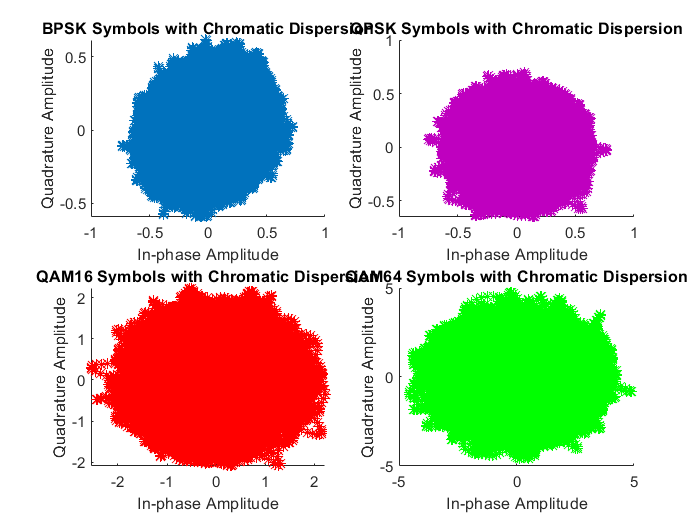

if enable_chromatic_dispersion
    
    D = 17*1e-6; %/s/m/m
    lambda = 1550e-9;
    z = 40e3;
    
    %For LMS Filter
    lms_bpsk = bpsk_mod;
    lms_qpsk = qpsk_mod;
    lms_qam16 = qam16_mod;
    lms_qam64 = qam64_mod;
    
    
    bpsk_mod = Chromatic_Dispersion(bpsk_mod,num_symbols,symbol_rate,D,z,lambda);
    qpsk_mod = Chromatic_Dispersion(qpsk_mod,num_symbols,symbol_rate,D,z,lambda);
    qam16_mod = Chromatic_Dispersion(qam16_mod,num_symbols,symbol_rate,D,z,lambda);
    qam64_mod = Chromatic_Dispersion(qam64_mod,num_symbols,symbol_rate,D,z,lambda);
    
    
    if enable_plots
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod),'*');
        title("BPSK Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with Chromatic Dispersion");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
    
end

## AWGN

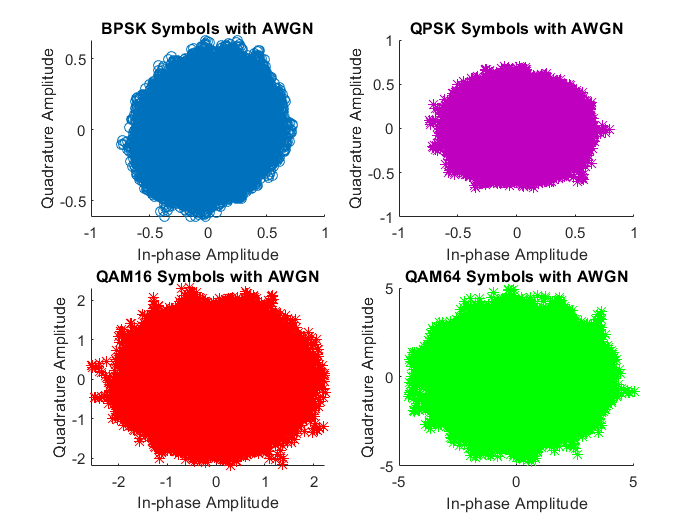

if enable_AWGN
    
    %AWGN with an SNR of 20dB (10,15,20,25,30,35,40)
    
    %SNR = Eb/No + 10log10(k) - 10log10(upsampling) 
    % To update properly in the future
    
    SNR_b = 20;
    SNR_q = 20;
    SNR_16 = 20;
    SNR_64 = 20;
    
    
    bpsk_mod = awgn(bpsk_mod,SNR_b,"measured");
    qpsk_mod = awgn(qpsk_mod,SNR_q,"measured");
    qam16_mod = awgn(qam16_mod,SNR_16,"measured");
    qam64_mod = awgn(qam64_mod,SNR_64,"measured");
    
    
    %Plots
    if enable_plots
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod));
        title("BPSK Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with AWGN");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
    
end

## Phase Noise

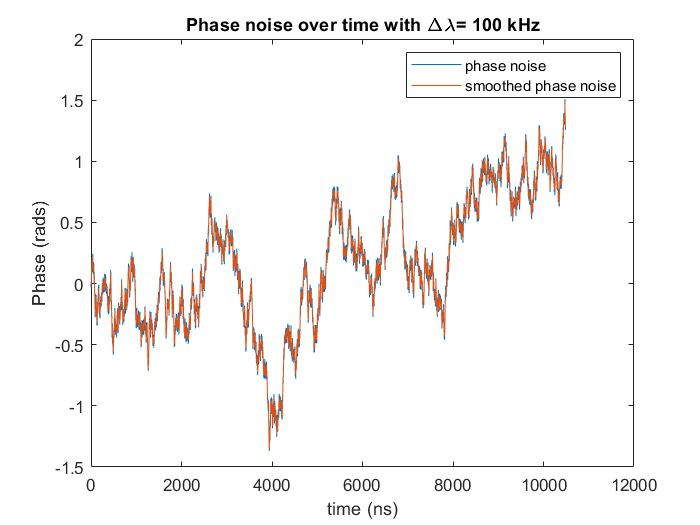

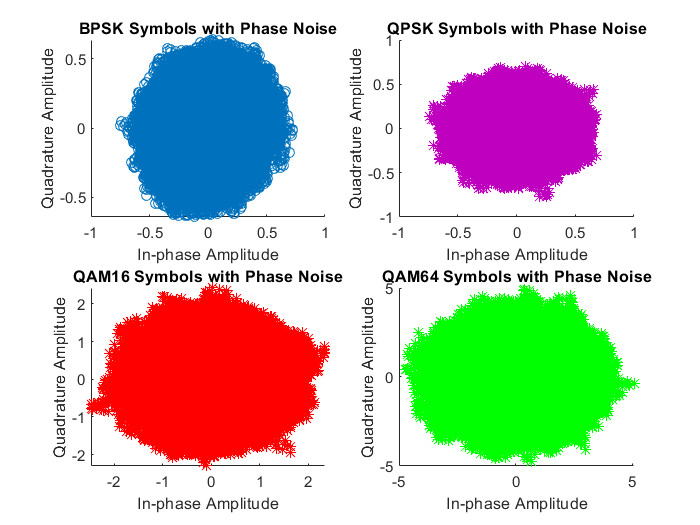

if enable_phase_noise
    
    %Generate Phase Noise
    rng(1960);
    num_sam = num_samples;
    
    if num_sam ~= length(bpsk_mod)   
        num_sam = length(bpsk_mod); 
    end
    
    phase_noise = randn(1,num_sam);
    
    random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
    
    t = (1:num_sam)*time_step*1e9; %in nanoseconds
    
    %Can try mixing phase noise with awgn noise to set its SNR
    
    %Apply Phase Noise
    
    bpsk_mod = bpsk_mod.*exp(1j*random_walk_phase_noise);
    qpsk_mod = qpsk_mod.*exp(1j*random_walk_phase_noise);
    qam16_mod = qam16_mod.*exp(1j*random_walk_phase_noise);
    qam64_mod = qam64_mod.*exp(1j*random_walk_phase_noise);
    
    
    if enable_plots
        figure
        plot(t,random_walk_phase_noise,t,filtfilt(ones(100,1)/100,1,random_walk_phase_noise));
        title('Phase noise over time with \Delta\lambda= 100 kHz');
        xlabel("time (ns)");
        ylabel("Phase (rads)");
        legend("phase noise","smoothed phase noise");
        
        figure
        subplot(2,2,1,gca);
        scatter(real(bpsk_mod),imag(bpsk_mod));
        title("BPSK Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,2);
        scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
        title("QPSK Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,3);
        scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
        title("QAM16 Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
        subplot(2,2,4);
        scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
        title("QAM64 Symbols with Phase Noise");
        xlabel("In-phase Amplitude");
        ylabel("Quadrature Amplitude");
    end
end

# **Transition into Electrical Domain (RX)**

## Matched Filter and Downconverting

if enable_pulse_shaping
         
     bpsk_mod = rx_ps_filter(bpsk_mod.').';
     qpsk_mod = rx_ps_filter(qpsk_mod.').';
     qam16_mod = rx_ps_filter(qam16_mod.').';
     qam64_mod = rx_ps_filter(qam64_mod.').';
     
end      

## **Inverse Chromatic Dispersion Model**

% if enable_chromatic_dispersion && enable_inv_cd
%         
%         %2*symbol_rate accounts for the downsampling and the 2 samples/symbol
%         
%         bpsk_mod = Inv_of_Chromatic_Dispersion(bpsk_mod,receiver_sample_rate,D,z,lambda);
%         qpsk_mod = Inv_of_Chromatic_Dispersion(qpsk_mod,receiver_sample_rate,D,z,lambda);
%         qam16_mod = Inv_of_Chromatic_Dispersion(qam16_mod,receiver_sample_rate,D,z,lambda);
%         qam64_mod = Inv_of_Chromatic_Dispersion(qam64_mod,receiver_sample_rate,D,z,lambda);
%         
%         
%         if enable_plots
%             figure
%             subplot(2,2,1,gca);
%             scatter(real(bpsk_mod),imag(bpsk_mod),'*');
%             title("BPSK Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,2);
%             scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
%             title("QPSK Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,3);
%             scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
%             title("QAM16 Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%             subplot(2,2,4);
%             scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
%             title("QAM64 Symbols with Chromatic Dispersion Inverted");
%             xlabel("In-phase Amplitude");
%             ylabel("Quadrature Amplitude");
%         end
% end

## Chromatic Dispersion Compensation

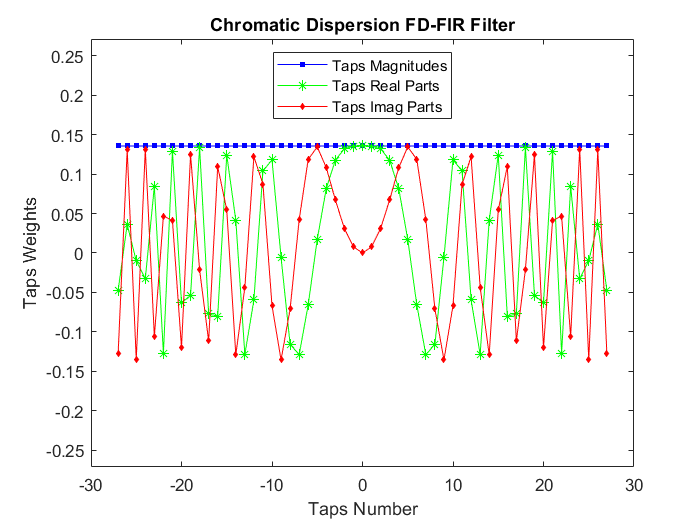

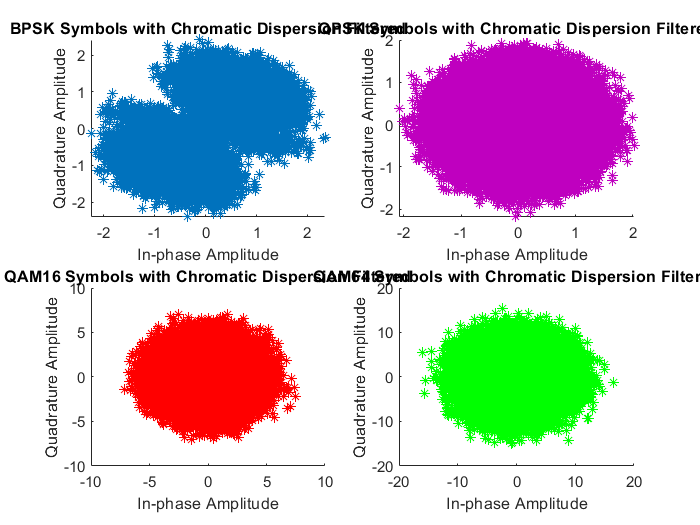

if enable_chromatic_dispersion
    %if (~enable_inv_cd)
        FD = true;
        OLS = false;
        
        
        if FD
            
            %Basic Chromatic Dispersion Filter
            CD_FD_FIR = CD_Filter(symbol_rate,D,z,lambda);
            l_tap = length(CD_FD_FIR);
            
            if enable_plots
                realfilt = real(CD_FD_FIR);
                imagfilt = imag(CD_FD_FIR);
                magfilt = abs(CD_FD_FIR);
                k = (-floor(length(CD_FD_FIR)/2):floor(length(CD_FD_FIR)/2));
                %fvtool(CD_FD_FIR);
                figure
                plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
                hold on
                plot(k,realfilt,"green","Marker","*");
                plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
                title("Chromatic Dispersion FD-FIR Filter");
                xlabel("Taps Number");
                ylabel("Taps Weights");
                ylim([-2*magfilt(1) 2*magfilt(1)]);
                legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
            end
        end
        
        if OLS
            
            OLS_FIR = OLS_filter(receiver_sample_rate,D,z,lambda);
            l_tap = length(OLS_FIR);
            
            if enable_plots
                realfilt = real(OLS_FIR);
                imagfilt = imag(OLS_FIR);
                magfilt = abs(OLS_FIR);
                k = (-floor(length(OLS_FIR)/2):floor(length(OLS_FIR)/2));
                %fvtool(OLS_FIR);
                figure
                plot(k,magfilt,"blue","Marker","square","MarkerFaceColor","blue","MarkerSize",3);
                hold on
                plot(k,realfilt,"green","Marker","*");
                plot(k,imagfilt,"red","Marker","diamond","MarkerFaceColor","red","MarkerSize",3);
                title("Chromatic Dispersion OLS-FIR Filter");
                xlabel("Taps Number");
                ylabel("Taps Weights");
                ylim([-2*max(magfilt) 2*max(magfilt)]);
                legend("Taps Magnitudes","Taps Real Parts","Taps Imag Parts","Location","north");
            end
            
        end
        
        %Filter signals to remove CD [Confusion between Filter(), and FFTfilt()]
        
        if FD
            
            %overlap-and-add
            bpsk_mod = fftfilt(CD_FD_FIR,bpsk_mod);
            qpsk_mod = fftfilt(CD_FD_FIR,qpsk_mod);
            qam16_mod = fftfilt(CD_FD_FIR,qam16_mod);
            qam64_mod = fftfilt(CD_FD_FIR,qam64_mod);
            
            
            %Overlap-and-save
            %fdf = dsp.FrequencyDomainFIRFilter("Numerator",CD_FD_FIR,"NumeratorDomain","Time","Method","Overlap-save");
            
            %bpsk_mod = fdf(bpsk_mod.').';
            %qpsk_mod = fdf(qpsk_mod.').';
            %qam16_mod = fdf(qam16_mod.').';
            %qam64_mod = fdf(qam64_mod.').';
            
            
        elseif OLS
            bpsk_mod = fftfilt(OLS_FIR,bpsk_mod);
            qpsk_mod = fftfilt(OLS_FIR,qpsk_mod);
            qam16_mod = fftfilt(OLS_FIR,qam16_mod);
            qam64_mod = fftfilt(OLS_FIR,qam64_mod); %,2^(ceil(log2(l_tap))+1) for FFT length 
            
        else
            %LMS Filter (Unsure how to implement)
                 lms = dsp.LMSFilter();
                 [lms_bpsk,~,~] = lms(bpsk_mod.',lms_bpsk.');
                 [lms_qpsk,~,~] = lms(qpsk_mod.',lms_qpsk.');
                 [lms_qam16,~,~] = lms(qam16_mod.',lms_qam16.');
                 [lms_qam64,lms_error,lms_weights] = lms(qam64_mod.',lms_qam64.');
            
                 bpsk_mod = lms_bpsk.';
                 qpsk_mod = lms_qpsk.';
                 qam16_mod = lms_qam16.';
                 qam64_mod = lms_qam64.';
        end
        
        if enable_plots
            figure
            subplot(2,2,1,gca);
            scatter(real(bpsk_mod),imag(bpsk_mod),'*');
            title("BPSK Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,2);
            scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
            title("QPSK Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,3);
            scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
            title("QAM16 Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
            subplot(2,2,4);
            scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
            title("QAM64 Symbols with Chromatic Dispersion Filtered");
            xlabel("In-phase Amplitude");
            ylabel("Quadrature Amplitude");
        end
    %end
end

## Adaptive Equalisation (CMA Algorithm)

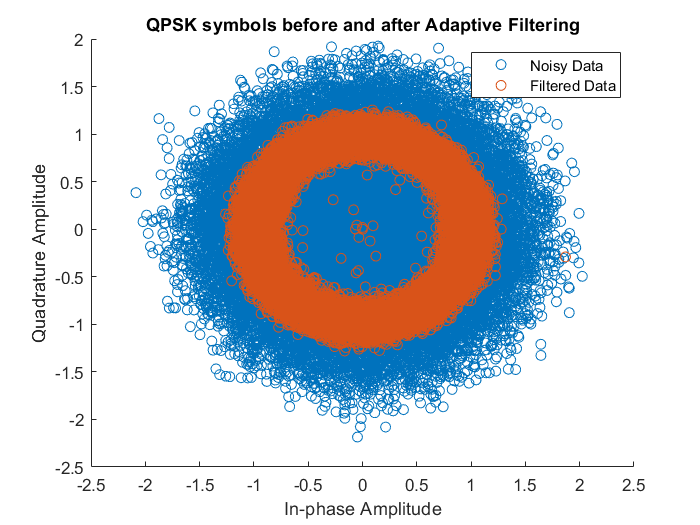

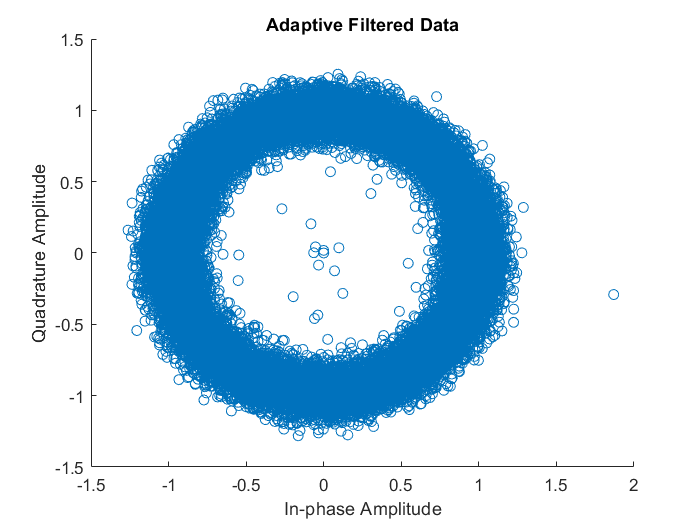

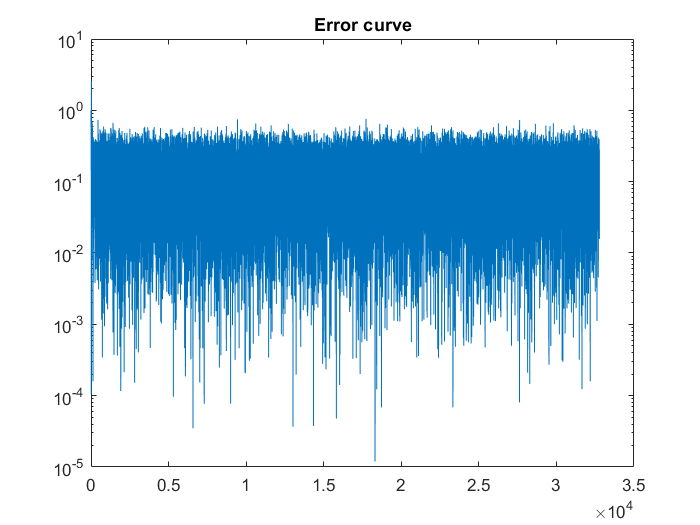

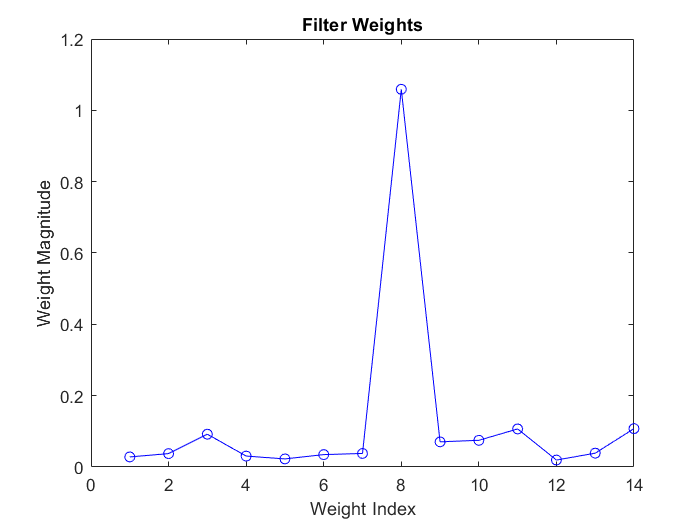

if enable_adaptive_eq
    
    x = qpsk_mod.'; %Received Input
    
    h_taps = 14; 
    mu = 0.0021; % Step Size
    
    h = zeros(h_taps,1);
    u = zeros(h_taps,1);
    
    h(floor(h_taps/2)+1) = 1;  
    length_after_eq = length(x)/receiver_samples_per_symbol;
    
    y = zeros([length_after_eq 1],'like', x);
    e = zeros([length_after_eq 1],'like', x);

    for i = 1:length_after_eq
        
         for j = h_taps:-1:receiver_samples_per_symbol+1
            u(j) = u(j-receiver_samples_per_symbol);
         end    
    
         for k=1:receiver_samples_per_symbol
            u(k,1) = x((i-1)*receiver_samples_per_symbol+k,1);
         end
         
         ytemp = h.' * u;
         etemp = 1 - abs(ytemp)^2;
         
         if abs(etemp)>1e-5
             mu = 0.011;
         else
             mu = 0.0022;
         end
         
         h = h + 2*mu*etemp*conj(u)*ytemp;
         y(i,1) = ytemp;         
         e(i,1) = etemp;
        %Filter 
%         
%         ytemp = h' * u; % We need the complex transpose in this case
%         
%         etemp = (1 - abs(ytemp).^2);
%         
%         if etemp>1e-5
%             mu = 0.011;
%         else
%             mu = 0.0022;
%         end
%         
%         etemp = ytemp*etemp;
%         
%         
%         h = h + mu*u*conj(etemp);
%         
%         y(i,1) = ytemp;
%         
%         e(i,1) = etemp;
        
    end    
    
    if enable_plots
        figure
        hold on
        scatter(real(qpsk_mod),imag(qpsk_mod));
        scatter(real(y),imag(y));
        legend("Noisy Data","Filtered Data");
        title("QPSK symbols before and after Adaptive Filtering");
        ylabel("Quadrature Amplitude");
        xlabel("In-phase Amplitude");
    end
    
%     for i =  training_size+1 : num_samples
%         
%     	temp = x(i:-1:i-h_taps+1) ;
%         
%         y(i) = h' * temp ;
%         
%         e(i) = 1 - abs(y(i))^2;
%     end
%     
        if enable_plots
            figure
            scatter(real(y),imag(y));
            title("Adaptive Filtered Data");
            ylabel("Quadrature Amplitude");
            xlabel("In-phase Amplitude");
            
            figure
            semilogy((abs(e))) ;
            title('Error curve');
            
            figure
            plot(abs(h),'bo-');
            title("Filter Weights");
            xlabel("Weight Index");
            ylabel("Weight Magnitude");
        end
    
    qpsk_mod = y.';
    
    
end



%%% Run through the entire set again with the generated taps

% x = qpsk_mod.';
% y = zeros([length_after_eq 1],'like', x);
% e = zeros([length_after_eq 1],'like', x);
%     
% for i = 1:length_after_eq
%         
%     for j = h_taps:-1:2
%             u(j) = u(j-1);
%     end    
%     
%     u(1,1) = x(i,1);
%       
%     ytemp = h.' * u;
%     etemp = 1 - abs(ytemp)^2;
%     
%     y(i,1) = ytemp;         
%     e(i,1) = etemp;
% end
%    
% qpsk_mod = y.';

## Downsampling

    %% This section chooses the best samples taken for the symbols
if enable_downsampling    
     if mean(abs(bpsk_mod(2:2:end)).^2)>mean(abs(bpsk_mod(1:2:end)).^2)
         bpsk_mod=bpsk_mod(2:2:end);
     else
         bpsk_mod=bpsk_mod(1:2:end);
     end
    
     if ~enable_adaptive_eq
         
         if mean(abs(qpsk_mod(2:2:end)).^2)>mean(abs(qpsk_mod(1:2:end)).^2)
             qpsk_mod=qpsk_mod(2:2:end);
         else
             qpsk_mod=qpsk_mod(1:2:end);
         end
         
     end
     
     if mean(abs(qam16_mod(2:2:end)).^2)>mean(abs(qam16_mod(1:2:end)).^2)
         qam16_mod=qam16_mod(2:2:end);
     else
         qam16_mod=qam16_mod(1:2:end);
     end
     
     if mean(abs(qam64_mod(2:2:end)).^2)>mean(abs(qam64_mod(1:2:end)).^2)
         qam64_mod=qam64_mod(2:2:end);
     else
         qam64_mod=qam64_mod(1:2:end);
     end
end     
     % From here on out revert to symbol rate

## Carrier Equalisation

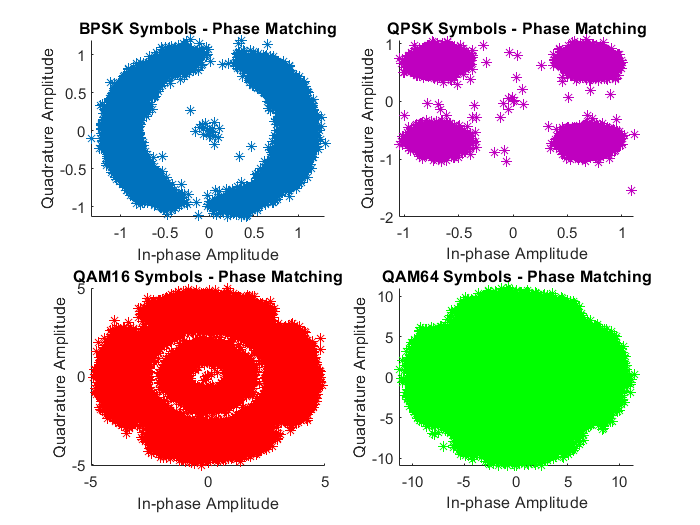

if enable_phase_noise || enable_chromatic_dispersion || enable_carrier_equal
    
%   t = (1:num_samples)*time_step*1e9; %in nanoseconds
%   low_pass_filtered_noise = zeros(1,num_samples);
    
    %Raise to the Mth power and low pass filter
    
    raised_phase_bpsk = bpsk_mod.^2;
    raised_phase_qpsk = qpsk_mod.^4;
    raised_phase_qam16 = qam16_mod.^4;
    raised_phase_qam64 = qam64_mod.^4;
    
    
    %Low pass filter with root raised cosine
    raised_phase_bpsk = filtfilt(ones(100,1)/100,1,raised_phase_bpsk);
    raised_phase_qpsk = filtfilt(ones(100,1)/100,1,raised_phase_qpsk);
    raised_phase_qam16 = filtfilt(ones(100,1)/100,1,raised_phase_qam16);
    raised_phase_qam64 = filtfilt(ones(100,1)/100,1,raised_phase_qam64);
    
    phase_estimate_bpsk = 1/2.*angle(mean(raised_phase_bpsk));
   % phase_estimate_qpsk = 1/4.*angle(mean(raised_phase_qpsk));
    
    %Different method for QAM as this wouldn't work based on the constellation
    phase_estimate_qam16 = 1/4*angle(-raised_phase_qam16)/4; 
    phase_estimate_qam64 = 1/4*angle(-raised_phase_qam64)/4;
    
    bpsk_mod = bpsk_mod.*exp(1j*pi/2-1j*phase_estimate_bpsk+3j*pi/2);
    %qpsk_mod = qpsk_mod.*exp(1j*pi/4-1j*phase_estimate_qpsk+3j*pi/2);
    qam16_mod = qam16_mod.*exp(1j*pi/4-1j*phase_estimate_qam16+3j*pi/2);
    qam64_mod = qam64_mod.*exp(1j*pi/4-1j*phase_estimate_qam64+3j*pi/2);
    
    chunk_length = 64;
    qpsk_mod = phase_correction(qpsk_mod,chunk_length);
    
    if enable_plots
%     figure
%     subplot(2,2,1,gca);
%     plot(t,phase_estimate_bpsk);
%     title("BPSK Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_bpsk)) 2*max(abs(phase_estimate_bpsk))]);
%     
%     subplot(2,2,2);
%     plot(t,phase_estimate_qpsk,'color',purple);
%     title("QPSK Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qpsk)) 2*max(abs(phase_estimate_qpsk))]);
%     
%     subplot(2,2,3);
%     plot(t,phase_estimate_qam16,'color','red');
%     title("QAM16 Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qam16)) 2*max(abs(phase_estimate_qam16))]);
%     
%     subplot(2,2,4);
%     plot(t,phase_estimate_qam64,'color','green');
%     title("QAM64 Phase Estimate");
%     xlabel("time (ns)");
%     ylabel("Phase (rads)");
%     ylim([-2*max(abs(phase_estimate_qam64)) 2*max(abs(phase_estimate_qam64))]);
%     
    figure
    subplot(2,2,1,gca);
    scatter(real(bpsk_mod),imag(bpsk_mod),'*');
    title("BPSK Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,2);
    scatter(real(qpsk_mod),imag(qpsk_mod),'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,3);
    scatter(real(qam16_mod),imag(qam16_mod),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
    title("QAM16 Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,4);
    scatter(real(qam64_mod),imag(qam64_mod),'*','MarkerEdgeColor','green','MarkerFaceColor','green');
    title("QAM64 Symbols - Phase Matching");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    
    end
end

## Alignment of Signals

    %%% Delay Compensation (Might need its own section)
if enable_alignment   
    if (~enable_FEC)
    if (~correl)
        %Simple Delay Compensation knowing filter tap lengths and delays
        
        bpsk_mod = bpsk_mod(1+span:end);
        qpsk_mod = qpsk_mod(1+span:end);
        qam16_mod = qam16_mod(1+span:end);
        qam64_mod = qam64_mod(1+span:end);
        
        %Removing lost symbols from shift
        
        symbols_b = symbols_b(1:end-span);
        symbols_q = symbols_q(1:end-span);
        symbols_16 = symbols_16(1:end-span);
        symbols_64 = symbols_64(1:end-span);
        
        
    else
        %Autocorellation method
        
        %Can be done after demodulation with knowleadge if sent signal, can set
        %up a preamble for detection before demodulation
        
        lag_b = finddelay(corr_bpsk,bpsk_mod);
        lag_q = finddelay(corr_qpsk,qpsk_mod);
        lag_16 = finddelay(corr_qam16,qam16_mod);
        lag_64 = finddelay(corr_qam64,qam64_mod);
        
        
 
        if lag_b > 0
            bpsk_mod = bpsk_mod(1+lag_b:end);
            symbols_b = symbols_b(1:end-lag_b);
        else
            lag_b = abs(lag_b);
            bpsk_mod = bpsk_mod(1:end-lag_b);
            symbols_b = symbols_b(1+lag_b:end);
        end
        
        if lag_q > 0
            qpsk_mod = qpsk_mod(1+lag_q:end);
            symbols_q = symbols_q(1:end-lag_q);
        else
            lag_q = abs(lag_q);
            qpsk_mod = qpsk_mod(1:end-lag_q);
            symbols_q = symbols_q(1+lag_q:end);
        end
        
        
        if lag_16 > 0
            qam16_mod = qam16_mod(1+lag_q:end);
            symbols_16 = symbols_16(1:end-lag_q);
        else
            lag_16 = abs(lag_16);
            qam16_mod = qam16_mod(1:end-lag_q);
            symbols_16 = symbols_16(1+lag_q:end);
        end
        
        
        if lag_64 > 0
            qam64_mod = qam64_mod(1+lag_q:end);
            symbols_64 = symbols_64(1:end-lag_q);
        else
            lag_64 = abs(lag_64);
            qam64_mod = qam64_mod(1:end-lag_q);
            symbols_64 = symbols_64(1+lag_q:end);
        end
        
        %%% Previous Implementation
        %     %BPSK
        %     [correlation,lags] = xcorr(bpsk_mod,corr_bpsk); %Matlab defined function
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr); %This should always be positive as filters always add delay, would need to be accounted for if it's not
        %
        %
        %     %QPSK
        %     [correlation,lags] = xcorr(qpsk_mod,corr_qpsk);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qpsk_mod = qpsk_mod(1+lag:end);
        %     symbols_q = symbols_q(1:end-lag);
        %
        %    %16QAM
        %     [correlation,lags] = xcorr(qam16_mod,corr_qam16);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qam16_mod = qam16_mod(1+lag:end);
        %     symbols_16 = symbols_16(1:end-lag);
        %
        %     %64QAM
        %     [correlation,lags] = xcorr(qam64_mod,corr_qam64);
        %     [~,idx_corr] = max(correlation);
        %     lag = lags(idx_corr);
        %
        %     if (lag < tap_length)
        %         lag = tap_length;
        %     end
        %
        %     qam64_mod = qam64_mod(1+lag:end);
        %     symbols_64 = symbols_64(1:end-lag);
        %
        %figure
        %plot(lags,real(correlation));
    end
    
    else
        
        [corr_bpsk,bpsk_mod] = alignsignals(corr_bpsk,bpsk_mod,[],'truncate');
        [corr_qpsk,qpsk_mod] = alignsignals(corr_qpsk,qpsk_mod,[],'truncate');
        [corr_qam16,qam16_mod] = alignsignals(corr_qam16,qam16_mod,[],'truncate');
        [corr_qam64,qam64_mod] = alignsignals(corr_qam64,qam64_mod,[],'truncate');
       
    end
end

## Frequency Equalisation

if enable_frequency_equal
    %This should happen earlier when implemented 
end

## Demodulation

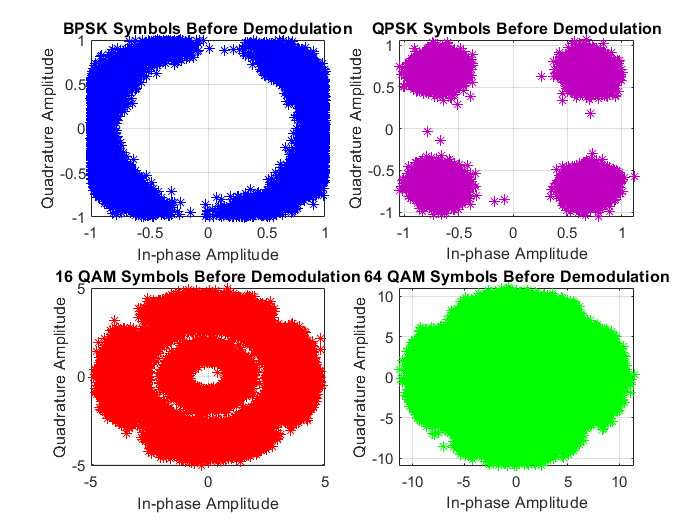


    figure
    subplot(2,2,1,gca);
    plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
    title("BPSK Symbols Before Demodulation");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    xlim([-1,1]);
    ylim([-1,1]);
    grid on;
    subplot(2,2,2);
    grid on;
    plot(qpsk_mod,'*','MarkerEdgeColor',purple,'MarkerFaceColor',purple);
    title("QPSK Symbols Before Demodulation");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,3);
    plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
    title("16 QAM Symbols Before Demodulation");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;
    subplot(2,2,4);
    plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
    title("64 QAM Symbols Before Demodulation");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    grid on;

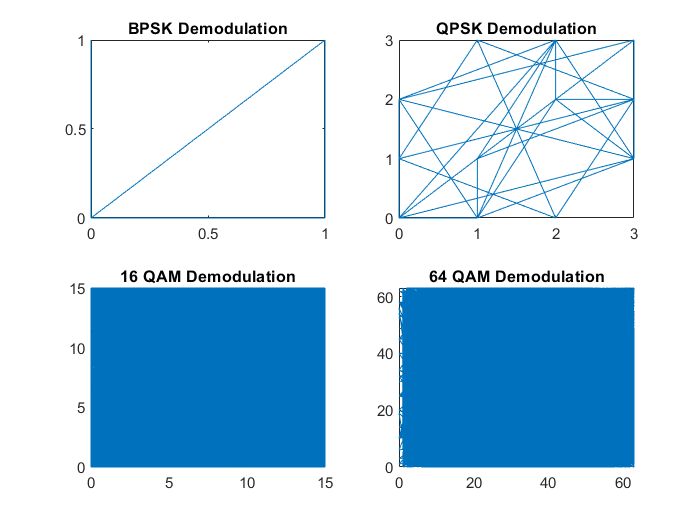




%BPSK

bpsk = pskdemod(bpsk_mod,M1,0,'gray');

%QPSK
qpsk = pskdemod(qpsk_mod,M2,pi/M2,'gray');

%16QAM
qam16 = qamdemod(qam16_mod,M3,'gray');

%64QAM
qam64 = qamdemod(qam64_mod,M4,'gray');

if (~enable_FEC)
    if enable_plots
        figure
        subplot(2,2,1,gca);
        plot(bpsk,symbols_b);
        title("BPSK Demodulation");
        subplot(2,2,2);
        plot(qpsk,symbols_q);
        title("QPSK Demodulation");
        subplot(2,2,3);
        plot(qam16,symbols_16);
        title("16 QAM Demodulation");
        subplot(2,2,4);
        plot(qam64,symbols_64);
        title("64 QAM Demodulation");
    end
end

## Decode FEC

if enable_FEC
    
    decLDPC = comm.LDPCDecoder(LDPC);
    
    
    %%% BPSK
    
    %% N-by-1 column vector of binary data where N = 64800
    if (mod(length(bpsk),LDPC_N)~=0)
        padding = (floor(length(bpsk)/LDPC_N)+1)*LDPC_N-length(bpsk);
    else
        padding = 0;
    end
    
    %BPSK Decoding
    bpsk = reshape(padarray(bpsk.',padding/2,"both"),LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(bpsk,2));
    
    for n=1:size(bpsk,2)
        symbols_temp(:,n) = ~decLDPC(bpsk(:,n));
    end
    %%% This line reorients bits for conversion back to higher order
    %%% modulation, not actually needed for bpsk
    bpsk = reshape(double(symbols_temp),log2(2),[]).';
    
    
    %%% QPSK
    
    %Padding for lost data
    if(mod(length(qpsk),LDPC_N)~=0)
        padding = (floor(length(qpsk)/LDPC_N)+1)*LDPC_N-length(qpsk);
    else
        padding = 0;
    end
    
    qpsk = padarray(qpsk.',padding/2,"both");
    
    %Symbols to Binary
    qpsk = dec2bin(qpsk,log2(4));
    qpsk = reshape(qpsk.',1,[]);
    qpsk = split(qpsk,"");
    qpsk = str2double(qpsk(2:end-1));
    
    %Decode
    qpsk = reshape(qpsk,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qpsk,2));
    
    for n=1:size(qpsk,2)
        symbols_temp(:,n) = decLDPC(qpsk(:,n));
    end
    
    %   qpsk = reshape(symbols_temp,[],1);
    
    qpsk = double(~symbols_temp);
    
    
    %Binary to Symbols
    qpsk = reshape(qpsk,log2(4),[]).';
    qpsk = string(qpsk);
    qpsk = join(qpsk,"",2);
    qpsk = bin2dec(qpsk).';
    
    
    %%% QAM16
    
    %Padding for lost data
    if(mod(length(qam16),LDPC_N)~=0)
        padding = (floor(length(qam16)/LDPC_N)+1)*LDPC_N-length(qam16);
    else
        padding = 0;
    end
    
    qam16 = padarray(qam16.',padding/2,"both");
    
    %Symbols to Binary
    qam16 = dec2bin(qam16,log2(16));
    qam16 = reshape(qam16.',1,[]);
    qam16 = split(qam16,"");
    qam16 = str2double(qam16(2:end-1));
    
    %Decode
    qam16 = reshape(qam16,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qam16,2));
    
    for n=1:size(qam16,2)
        symbols_temp(:,n) = decLDPC(qam16(:,n));
    end
    
    qam16 = double(~symbols_temp);
    
    
    %Binary to Symbols
    qam16 = reshape(qam16,log2(16),[]).';
    qam16 = string(qam16);
    qam16 = join(qam16,"",2);
    qam16 = bin2dec(qam16).';
    
    
    %%% QAM64
    
    %Padding for lost data
    if(mod(length(qam64),LDPC_N)~=0)
        padding = (floor(length(qam64)/LDPC_N)+1)*LDPC_N-length(qam64);
    else
        padding = 0;
    end
    
    qam64 = padarray(qam64.',padding/2,"both");
    
    %Symbols to Binary
    qam64 = dec2bin(qam64,log2(64));
    qam64 = reshape(qam64.',1,[]);
    qam64 = split(qam64,"");
    qam64 = str2double(qam64(2:end-1));
    
    %Decode
    qam64 = reshape(qam64,LDPC_N,[]);
    
    symbols_temp = nan(LDPC_K,size(qam64,2));
    
    for n=1:size(qam64,2)
        symbols_temp(:,n) = decLDPC(qam64(:,n));
    end
    
    qam64 = double(~symbols_temp);
    
    
    %Binary to Symbols
    qam64 = reshape(qam64,log2(64),[]).';
    qam64 = string(qam64);
    qam64 = join(qam64,"",2);
    qam64 = bin2dec(qam64).';
    
end

##  BER

if enable_FEC
    
    %Remove Padding from decoded array
    padding = length(bpsk) - num_symbols;
    bpsk = bpsk(1+padding/2:end-padding/2);
    [~,BPSK_BER] = biterr(symbols_bi,bpsk,log2(2));
    
    
    padding = length(qpsk) - num_symbols;
    qpsk = qpsk(1+padding/2:end-padding/2);
    [~,QPSK_BER] = biterr(symbols_qi.',qpsk,log2(4));
    
    
    padding = length(qam16) - num_symbols;
    qam16 = qam16(1+padding/2:end-padding/2);
    [~,QAM16_BER] = biterr(symbols_16i.',qam16,log2(16));
    
    
    padding = length(qam64) - num_symbols;
    qam64 = qam64(1+padding/2:end-padding/2);
    [~,QAM64_BER] = biterr(symbols_64i.',qam64,log2(64));

    BERs = [BPSK_BER QPSK_BER QAM16_BER QAM64_BER]
else
    [ERRORS_B,BPSK_BER] = biterr(symbols_b,bpsk,log2(2));
    [ERRORS_Q,QPSK_BER] = biterr(symbols_q,qpsk,log2(4));
    [ERRORS_16,QAM16_BER] = biterr(symbols_16,qam16,log2(16));
    [ERRORS_64,QAM64_BER] = biterr(symbols_64,qam64,log2(64));
    
    BERs = [BPSK_BER QPSK_BER QAM16_BER QAM64_BER]
    
end

BERs =     0.0002    0.0939    0.4987    0.5013


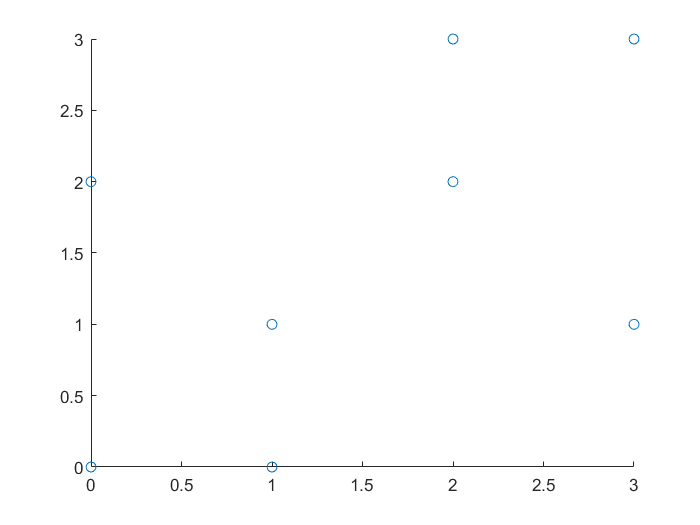

figure
scatter(symbols_q(1,10000:15000),qpsk(1,10000:15000))

toc

Elapsed time is 78.434854 seconds.



%BER vs SNR (floor(end/2):end)